syms R alpha t
assume(R, {'real', 'positive'})
assume(t, {'real', 'positive'})
assume(alpha, {'real'})

ri = R*cos(alpha*t);
rj = R*sin(alpha*t);
r = [ri, rj, 0]

$$r = \left(\begin{array}{ccc} R\,\cos\left(\alpha \,t\right) & R\,\sin\left(\alpha \,t\right) & 0 \end{array}\right)$$

vel = diff(r)

$$vel = \left(\begin{array}{ccc} -R\,\alpha \,\sin\left(\alpha \,t\right) & R\,\alpha \,\cos\left(\alpha \,t\right) & 0 \end{array}\right)$$

speed = simplify(norm(vel))

$$speed = R\,\left|\alpha \right|$$

T = simplify(vel ./ norm(vel))

$$T = \left(\begin{array}{ccc} -\frac{\alpha \,\sin\left(\alpha \,t\right)}{\left|\alpha \right|} & \frac{\alpha \,\cos\left(\alpha \,t\right)}{\left|\alpha \right|} & 0 \end{array}\right)$$

dT = diff(T);
N = simplify(dT ./ norm(dT))

$$N = \left(\begin{array}{ccc} -\cos\left(\alpha \,t\right) & -\sin\left(\alpha \,t\right) & 0 \end{array}\right)$$

w = simplify(cross(T, dT))

$$w = \left(\begin{array}{ccc} 0 & 0 & \alpha \end{array}\right)$$

syms d
assume(d, {'real', 'positive'})

V_L = simplify(V_T - w(3) * d / 2)

$$V\_L = \frac{R\,\alpha^{2}}{\left|\alpha \right|}-\frac{\alpha \,d}{2}$$

V_R = simplify(V_T + w(3) * d / 2)

$$V\_R = \frac{\alpha \,d}{2}+\frac{R\,\alpha^{2}}{\left|\alpha \right|}$$

double(subs(V_L, [R, alpha, d], [1, 0.209, 0.235]))

ans = 0.1844

double(subs(V_R, [R, alpha, d], [1, 0.209, 0.235]))

ans = 0.2336

clear

syms a b alpha t

assume(a, {'real', 'positive'})
assume(b, {'real', 'positive'})
assume(alpha, {'real', 'positive'})
assume(t, {'real', 'positive'})

ri = a * cos(alpha*t);
rj = b * sin(alpha*t);
r = [ri, rj, 0]

$$r = \left(\begin{array}{ccc} a\,\cos\left(\alpha \,t\right) & b\,\sin\left(\alpha \,t\right) & 0 \end{array}\right)$$

vel = diff(r, t)

$$vel = \left(\begin{array}{ccc} -a\,\alpha \,\sin\left(\alpha \,t\right) & \alpha \,b\,\cos\left(\alpha \,t\right) & 0 \end{array}\right)$$

T = simplify(vel ./ norm(vel))

$$T = \left(\begin{array}{ccc} -\frac{a\,\sin\left(\alpha \,t\right)}{\sqrt{a^{2}\,{\sin\left(\alpha \,t\right)}^{2}-b^{2}\,{\sin\left(\alpha \,t\right)}^{2}+b^{2}}} & \frac{b\,\cos\left(\alpha \,t\right)}{\sqrt{a^{2}\,{\sin\left(\alpha \,t\right)}^{2}-b^{2}\,{\sin\left(\alpha \,t\right)}^{2}+b^{2}}} & 0 \end{array}\right)$$

dT = diff(T, t);
N = simplify(dT ./ norm(dT))

$$N = \left(\begin{array}{ccc} -\frac{b\,\cos\left(\alpha \,t\right)}{\sqrt{-a^{2}\,{\cos\left(\alpha \,t\right)}^{2}+a^{2}+b^{2}\,{\cos\left(\alpha \,t\right)}^{2}}} & -\frac{a\,\sin\left(\alpha \,t\right)}{\sqrt{a^{2}\,{\sin\left(\alpha \,t\right)}^{2}-b^{2}\,{\sin\left(\alpha \,t\right)}^{2}+b^{2}}} & 0 \end{array}\right)$$

w = simplify(cross(T, dT))

$$w = \left(\begin{array}{ccc} 0 & 0 & \frac{2\,a\,\alpha \,b}{b^{2}\,\cos\left(2\,\alpha \,t\right)-a^{2}\,\cos\left(2\,\alpha \,t\right)+a^{2}+b^{2}} \end{array}\right)$$

V_T = simplify(dot(T, vel))

$$V\_T = \frac{\alpha \,\left(a^{2}\,{\sin\left(\alpha \,t\right)}^{2}-b^{2}\,{\sin\left(\alpha \,t\right)}^{2}+b^{2}\right)}{\bar{\sqrt{a^{2}\,{\sin\left(\alpha \,t\right)}^{2}-b^{2}\,{\sin\left(\alpha \,t\right)}^{2}+b^{2}}}}$$

syms d
assume(d, {'real', 'positive'})

V_L = simplify(V_T - w(3) * d / 2)

$$V\_L = \begin{array}{l} \frac{\alpha \,\sigma_{1}}{\bar{\sqrt{\sigma_{1}}}}-\frac{a\,\alpha \,b\,d}{b^{2}\,\cos\left(2\,\alpha \,t\right)-a^{2}\,\cos\left(2\,\alpha \,t\right)+a^{2}+b^{2}}\\ \mathrm{where}\\ \sigma_{1}=a^{2}\,{\sin\left(\alpha \,t\right)}^{2}-b^{2}\,{\sin\left(\alpha \,t\right)}^{2}+b^{2} \end{array}$$

V_R = simplify(V_T + w(3) * d / 2)

$$V\_R = \begin{array}{l} \frac{\alpha \,\sigma_{1}}{\bar{\sqrt{\sigma_{1}}}}+\frac{a\,\alpha \,b\,d}{b^{2}\,\cos\left(2\,\alpha \,t\right)-a^{2}\,\cos\left(2\,\alpha \,t\right)+a^{2}+b^{2}}\\ \mathrm{where}\\ \sigma_{1}=a^{2}\,{\sin\left(\alpha \,t\right)}^{2}-b^{2}\,{\sin\left(\alpha \,t\right)}^{2}+b^{2} \end{array}$$

a_num = 1;
b_num = 2;
t_num = linspace(0,1,100);
w_num = 2*pi;

v_num = zeros(3, size(t_num, 2));

for n=1:length(t_num)
    v_num(:, n) = double(subs(vel,[a, b, t, alpha],[a_num, b_num, t_num(n), w_num]));
end

vl_num = zeros(size(t_num));
vr_num = zeros(size(t_num));
a_num = 1;
b_num = 2;
t_num = linspace(0,10,1000);
w_num = 2*pi / 10;
d_num = 0.235;

for n=1:length(t_num)
    vl_num(n) = double(subs(V_L,[a, b, t, alpha, d],[a_num, b_num, t_num(n), w_num, d_num]));
    vr_num(n) = double(subs(V_R,[a, b, t, alpha, d],[a_num, b_num, t_num(n), w_num, d_num]));
end

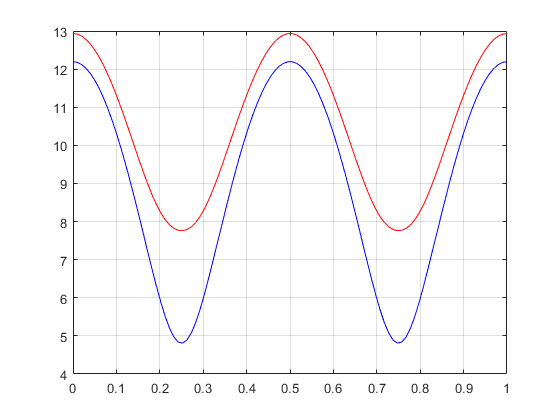

plot(t_num, vl_num, 'b', t_num, vr_num, 'r')
grid on